syms y t t2 n;
ttt1=0; %TIME START POINT
T=200;
dt=0.01;
% t0=[0, 20, 40, 60, 80, 100];
t0=0;
N = 83; % should be consistent with DNS's Ny
L = 2;
kx = 1.2;
kz = 0;
Re = 500;
% [x, Dy, Dyy, D4, w] = finitediff(N, L);
[x, D, D2, D4, w] = finitediff(N, L);
Ny = length(x);   % interior grid points

h=eye(size(D));
h1=eye(size(D));
k2=(kx.^2+kz.^2)*h;
k=(kx.^2+kz.^2).^0.5*h1;
w1=w.^0.5;
W=diag(w1);
d=D+k;
WW=W*d;

%v
V=[WW,zeros(N-2,N-2);zeros(N-2,N-2),W]; %126*126
c=D2-k2;
Cn = 0;
NN=100;
k0 = 0.1;
% Re= 500;
% g=1-exp(-k0.*t); %Acc
g=exp(-k0.*t); %Dec
an = (pi*n).^2./Re;  %lately
m=diff(g,t);
a1=subs(m,t,0);
m2=diff(m,t);
a2=subs(m2,t,t2);
e=exp(an.*t2);
a3=simplify(e*a2);
a4=simplify(int(a3, t2, 0, t),'Steps',200);
a5=a4+a1;
aa=-2.*Re.*(-1).^n./(pi.*n).^3.*(a5)+Cn;
a6=simplify(aa.*exp(-an.*t).*sin(n.*y.*pi),'Steps',100);
b1=Re./6.*m.*(y.^3-y);
b2=g.*y;
bb=b1+b2;
a7 = 0;
for ii = 1:NN
    a7 = a7 + subs(a6, n, ii);
end
U=a7+bb;
o=1/(1i*Re)*(D4-2*D2*k2+k2*k2);
oo=-inv(c); % inverse laplace
ooo=(1/(1i*Re))*c;
mm=diff(U);
mm2=diff(mm);
% U_yi = (subs(U, y, yi(2:N)));
% m_yi = (subs(mm, y, yi(2:N)));
% m2_yi = (subs(mm2, y, yi(2:N)));

U_yi = (subs(U, y, x));
m_yi = (subs(mm, y, x));
m2_yi = (subs(mm2, y, x));
U_yi_function = matlabFunction(U_yi);
U_function_space_time = matlabFunction(U, 'Vars', {y, t});
% m_yi_function = matlabFunction(m_yi);
% m2_yi_function = matlabFunction(m2_yi);

filename = 'snapshots_channel_9/snapshots_channel_s1.h5';

% Read necessary datasets
y_2 = readDatasetByPrefix(filename, '/scales', 'y_hash_');

Found dataset: /scales/y_hash_5a2a99716275a5a7f9566cda0b1170033dcad96a


t = h5read(filename, '/scales/sim_time');   % simulation time

% Read the velocity field 'u'
u = readDatasetByPrefix(filename, '/tasks', 'u');  % adjust path if 'u' is in a sub-group

Found dataset: /tasks/u


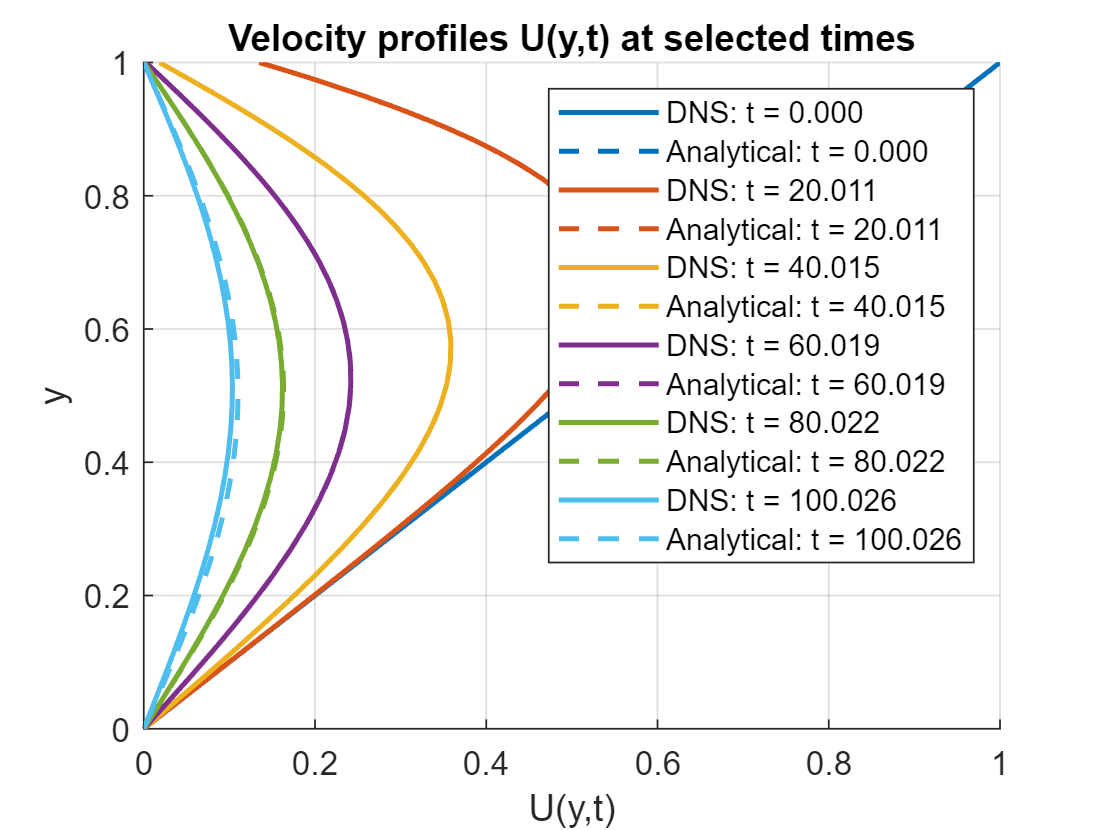


u_x = squeeze(u(:,:,:,1,:));  % size = [z, y, x, component, time]
% mesh(squeeze(u_x(1,:,1,:)))

U_y_t = squeeze(mean(mean(u(:,:,:,1,:),1),3));
target_times = [0, 20, 40, 60, 80, 100];
cmap = lines(length(target_times));
hold on;
for i = 1:length(target_times)
    % Find nearest index to desired time
    [~, ti] = min(abs(t - target_times(i)));
    
    % Plot numerical profile at that time
    plot(U_y_t(:,ti), y_2, 'DisplayName', sprintf('DNS: t = %.3f', t(ti)),'Color', cmap(i,:),'LineWidth', 1.5);
    
    % Optional: plot analytical profile if U_yi_function is vectorized properly
    Uy_pred = U_yi_function(t(ti));
    plot(Uy_pred, x, '--','DisplayName', sprintf('Analytical: t = %.3f', t(ti)),'Color', cmap(i,:),'LineWidth', 1.5);
end

hold off;
xlabel('U(y,t)');
yaxis(0,1);
ylabel('y');
title('Velocity profiles U(y,t) at selected times');
legend('show');
grid on;

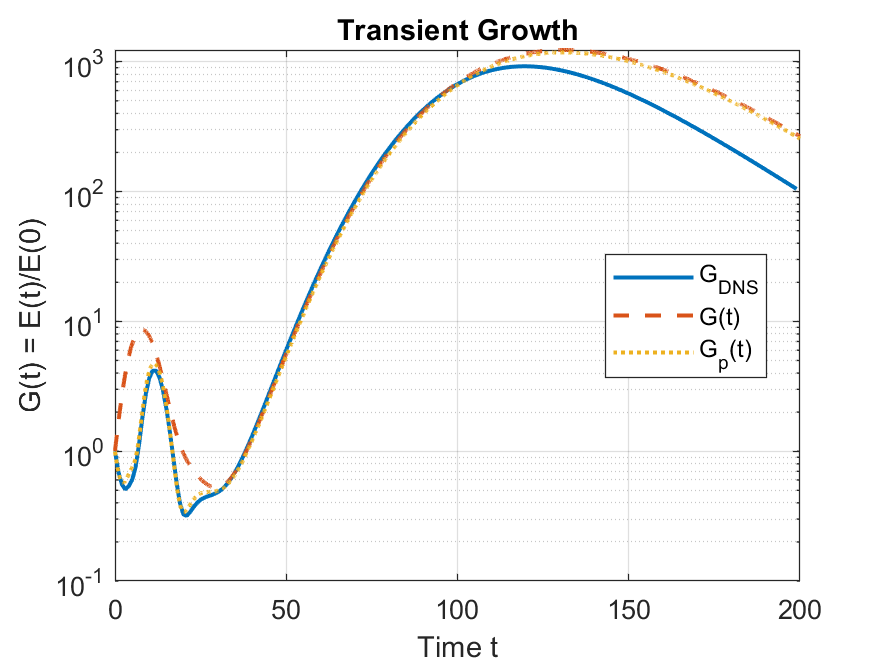


Nt = size(u, 5);
E_pert = zeros(1, Nt); 
Nx = size(u,3); Ny = size(u,2); Nz = size(u,1);
alphaopt = 1.2;
betaopt= 0; 
Lx = 2*pi/alphaopt; Ly = 2; Lz = 1;                % or 2*pi/betaopt when used
dx = Lx / Nx; dz = Lz / Nz;
dy = Ly /Ny;

for ti = 1:Nt
    % velocity components
    ux = squeeze(u(:,:,:,1,ti)); % Nz=2; Ny=64; Nx=32;Comp:3;t:200
    uy = squeeze(u(:,:,:,2,ti));
    uz = squeeze(u(:,:,:,3,ti));

    % laminar base flow
    Ulam = U_function_space_time(y_2, t(ti)); 
    Ulam = Ulam(:);
    Ubase = repmat(reshape(Ulam,1,Ny,1), Nz, 1, Nx);

    % perturbation
    up = ux - Ubase;
    % up = ux
    vp = uy;
    wp = uz;
    
   % pointwise KE density
    KE = 0.5*(up.^2 + vp.^2 + wp.^2);  % Nz x Ny x Nx
    
    % integrate over x and z (uniform grids)
    KE_y = squeeze(sum(sum(KE,1),3));
    E_DNS(ti) = dx * dz * trapz(y_2, KE_y);
end

G_DNS = E_DNS / E_DNS(1);%/ E_DNS(1);
figure; 
semilogy(t, G_DNS, '-', LineWidth=1.5);
hold on
plot(ttt,G,'--',LineWidth=1.5);
plot(ttt, Gp, ':',LineWidth=1.5);
xlabel('Time t');
ylabel('G(t) = E(t)/E(0)'); 
legend('G_{DNS}', 'G(t)', 'G_p(t)', 'Location', 'best');
title('Transient Growth');
grid on;

function data = readDatasetByPrefix(filename, groupPath, prefix)
% readDatasetByPrefix  Read dataset from an HDF5 group by matching prefix
%
%   data = readDatasetByPrefix(filename, groupPath, prefix)
%
%   Example:
%       y = readDatasetByPrefix('output/data_s1.h5', '/scales', 'y_hash_');
%

    info = h5info(filename, groupPath);
    data = [];

    for i = 1:length(info.Datasets)
        dset = info.Datasets(i);
        if startsWith(dset.Name, prefix)
            dset_path = [groupPath '/' dset.Name];
            data = h5read(filename, dset_path);
            fprintf('Found dataset: %s\n', dset_path);
            return;
        end
    end

    error('No dataset starting with "%s" found in %s.', prefix, groupPath);
end

function [x, D1, D2, D4,w] =finitediff(N,L)

%Differentiation matrix using finite difference scheme.
%This is suitable for Dirichlet boundary condition v(x=L/2)=v(x=-L/2)=0 at
%the boundary and Neumann boundary condition v'(x=L/2)=v'(x=-L/2)=0. 

dx=L/N;%get grid spacing. 

x=linspace(-L/2,L/2,N);%get the grid point location

x=x(2:end-1); %delete the first and last points that are zero. 

w=dx*ones(1,N-2);%integration weighting 

N_diff=N-2;%The size of differentiation matrices

%First order derivative based on central difference
%f'(x_i)=(f(x_{i+1})-f(x_{i-1})/(2*dx)
%We also use the boundary condition that x_0=x_N=0
D1_stencil=diag(-1*ones(1,N_diff-1),1)+diag(ones(1,N_diff-1),-1);
D1=D1_stencil/(2*dx);

%Second order derivative based on central difference
%f''(x_i)=(f(x_{i+1})-2f(x_i)+f(x_{i-1})/(dx^2)
%We also use the boundary condition that x_0=x_N=0
D2_stencil=(diag(-2*ones(1,N_diff))+diag(ones(1,N_diff-1),1)+diag(ones(1,N_diff-1),-1));
D2=D2_stencil/dx^2;

%Forth order derivative based on central difference
%f''''(x_i)=(f(x_{i+2})-4f(x_{i+1})+6f(x_i)-4f(x_{i-1})+f(x_{i-2})/(dx^4)
%This differentiation matrix only go through x_1 up to x_{N-1}
D4_stencil=(diag(6*ones(1,N_diff))+diag(-4*ones(1,N_diff-1),1)+diag(-4*ones(1,N_diff-1),-1)...
    + diag(ones(1,N_diff-2),2)+diag(ones(1,N_diff-2),-2));

%Here, we use the Neumann boundary condition that x_0'=x_N'=0
%such that x_1=x_{-1} and x_{N-1}=x_{N+1} for the ghost points. Then we
%also use the condition x_0 and x_N=0 to express all values based on x_1 up
%to x_{N-1}
D4_stencil(1,1)=D4_stencil(1,1)+1;
D4_stencil(end,end)=D4_stencil(end,end)+1;

D4=D4_stencil/dx^4;
end

